# Polynomial interpolation

Funzione seno. Genera dei punti rumorosi che seguono l'andamento del seno e poi determina il polinomio che passa per i punti. Grafica anche gli errori di Learning e Testing e individua il minimo

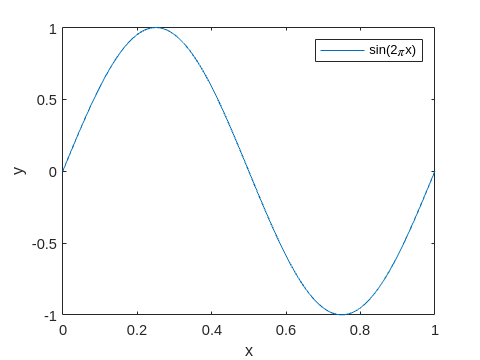

% cleaning
clc
clear

% genero vettori
x = linspace(0,1,100);
y = sin(2*pi*x);

% plotto funzione seno
figure;
plot(x,y)
xlabel("x")
ylabel("y")
legend("sin(2\pix)")

In general, you can generate `N` random numbers in the interval (a,b) with the formula `r = a + (b-a).*rand(N,1)`.

% genero set di learning
n_lrn = 10;
x_lrn = linspace(0,1,n_lrn)

x_lrn =          0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000


eps = 0.15;
y_lrn = sin(2*pi*x_lrn)

y_lrn =          0    0.6428    0.9848    0.8660    0.3420   -0.3420   -0.8660   -0.9848   -0.6428   -0.0000


y_lrn = y_lrn + (-eps + (2.*eps).*rand(n_lrn,1))'

y_lrn =    -0.1013    0.7311    0.9282    0.8746    0.2417   -0.3114   -0.9371   -0.9386   -0.5860    0.0744


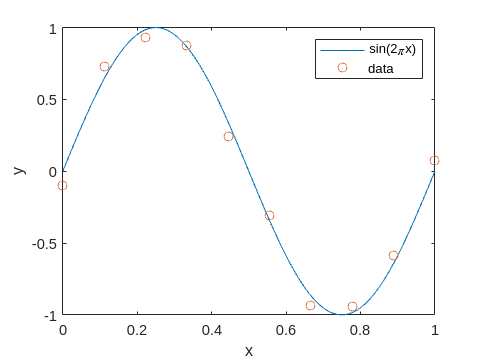


figure
plot(x,y)
hold on
plot(x_lrn,y_lrn,"o")
legend("sin(2\pix)","data")
xlabel("x")
ylabel("y")
hold off

% genero matrice di Vandermonde
V = fliplr(vander(x_lrn))

V =     1.0000         0         0         0         0         0         0         0         0         0
    1.0000    0.1111    0.0123    0.0014    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.2222    0.0494    0.0110    0.0024    0.0005    0.0001    0.0000    0.0000    0.0000
    1.0000    0.3333    0.1111    0.0370    0.0123    0.0041    0.0014    0.0005    0.0002    0.0001
    1.0000    0.4444    0.1975    0.0878    0.0390    0.0173    0.0077    0.0034    0.0015    0.0007
    1.0000    0.5556    0.3086    0.1715    0.0953    0.0529    0.0294    0.0163    0.0091    0.0050
    1.0000    0.6667    0.4444    0.2963    0.1975    0.1317    0.0878    0.0585    0.0390    0.0260
    1.0000    0.7778    0.6049    0.4705    0.3660    0.2846    0.2214    0.1722    0.1339    0.1042
    1.0000    0.8889    0.7901    0.7023    0.6243    0.5549    0.4933    0.4385    0.3897    0.3464
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0

Risolvo il sistema lineare $y = \alpha V$ dove $\alpha$ sono i coefficienti del polinomio cercato: $y = \alpha_1 + \alpha_2 x_1 + \alpha_3 x_2^2+...$

Alla luce della forma matriciale, i coefficienti $\alpha$ eseguendo il prodotto righe per colonna tra l'inversa della matrice di Vandermonde e il vettore colonna y

% determino i coefficienti
a = pinv(V)*(y_lrn')

a = 1.0e+05 *

   -0.0000
    0.0007
   -0.0146
    0.1275
   -0.5903
    1.5908
   -2.5842
    2.4933
   -1.3148
    0.2916


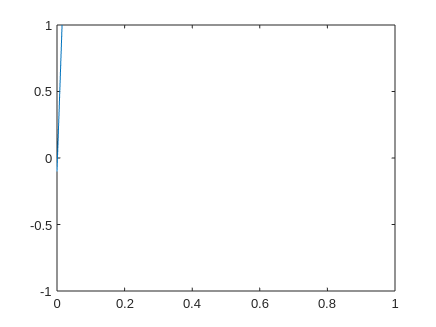


% ottengo il polinomio
figure;
plot(x_lrn, (a(1) + a(2).*x_lrn))
ylim([-1 1])
xlim([0 1])

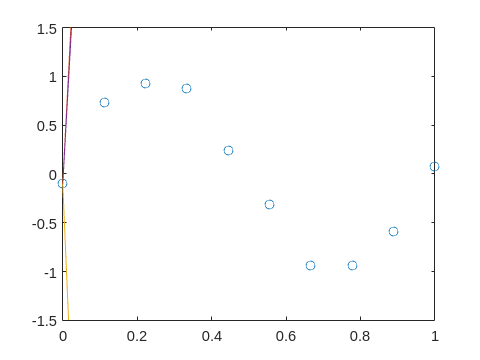


% test plot
figure;
plot(x_lrn,y_lrn,"o")
hold on
plot(x_lrn, (a(1) + a(2).*x_lrn))
plot(x_lrn, (a(1) + (a(2).*x_lrn) + (a(3).*x_lrn.^2)))
plot(x_lrn, (a(1) + (a(2).*x_lrn) + (a(3).*x_lrn.^2) + a(4).*x_lrn.^3))
hold off
xlim([0 1])
ylim([-1.5 1.5])